## Supplemental script to "Simulation of Steady State Energy Metabolism in Cyling and Running"

### Script for creating Figure 2

*Script written by Oliver Jan Quittmann in 2019 and commented by Simon Nolte in 2022.*

####  Setup

clc
clearvars
close all

% Define colours
blue = [0 0 1];
red = [1 0.2 0];

% Define line sizes
thick = 3;

#### Set values

% Specify ADP range
ADP(:,1) = 0:0.001:1000;

% Specify constants
kox = 0.25;
nox = 2;
kLa = 1.1;
nLa = 3;

VO2max = 1;
VLamax = 1;

% Calculuate activation lines
    for a = 1:length(ADP)
VO2_base(a,1) = (VO2max/(1+(kox/(ADP(a)))^nox));
VLa_base(a,1) = (VLamax/(1+(kLa/(ADP(a)))^nLa));
    end
       
VO2 = VO2_base/ VO2max;
VLa = VLa_base/ VLamax;

#### Create plot

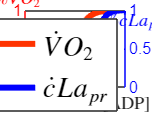

% Set colours
colororder({'red','blue'})
% Plot lines
yyaxis left
semilogx(ADP,VO2,'-','LineWidth',thick, 'Color', red);
hold on
yyaxis right
semilogx(ADP,VLa,'-','LineWidth',thick, 'Color', blue);

% Set axes and labels
x = xlabel('[ADP]', 'interpreter','latex','fontweight','bold');

yyaxis left

y = ylabel('$\%\dot{V}O_2$', 'interpreter','latex');
set(y, 'Position', [0.0058 0.99 -1], 'Rotation', 0);
set(x, 'Position', [10 -0.07 -1], 'Rotation', 0);
yyaxis right
y = ylabel('$\%\dot{c}La_{pr}$', 'interpreter','latex');
set(y, 'Position', [16.5 1.04 -1], 'Rotation', 0);
%set(x, 'Position', [1000 0 -1], 'Rotation', 0)
%l_legend = legend ('$\frac{1}{5}$','$\frac{1}{4}$','$\frac{1}{3}$','$\frac{1}{2}$','1','2','3','4','5', 'interpreter','latex','Location','southeast');
l_legend = legend ('$\dot{V}O_{2}$','$\dot{c}La_{pr}$', 'interpreter','latex','Location','southeast','FontSize',14);
%t = title('{\dot{V}O_{2,max}','interpreter','latex', 'FontSize',20, 'FontWeight', 'bold');
axis ([0.01, 10, 0, 1]);

#### Write plot file

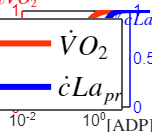

set(gcf,'PaperUnits','inches','PaperPosition',[0 0 8 6])
FigureTitle_print = strcat({'../plots/Fig2'});
path_name = fullfile('.', '..', '/plots/Fig2.png');
print(path_name,'-dpng', '-r1000');